%standard length 9000s, segment long signal and remove short signals
parfor i=1:length(Labels)
    Signals{i} = MoV(wdata{i});
end

Labels = cellstr(Labels);
[data, labels] = SegmentSignals(Signals, Labels, 9000);
Labels = categorical(labels);
summary(Labels);

     A       718 
     N      4937 
     O      2603 
     ~       151 



%divide training and testing set
A = Labels(Labels == 'A');
ASig = data(Labels == 'A');
N = Labels(Labels == 'N');
NSig = data(Labels == 'N');
O = Labels(Labels == 'O');
OSig = data(Labels == 'O');

[trainIndA,~,testIndA] = dividerand(length(A),0.9,0.0,0.1);
[trainIndN,~,testIndN] = dividerand(length(N),0.9,0.0,0.1);
[trainIndO,~,testIndO] = dividerand(length(O),0.9,0.0,0.1);

XTrainA = ASig(trainIndA);
YTrainA = A(trainIndA);

XTrainN = NSig(trainIndN);
YTrainN = N(trainIndN);

XTrainO = OSig(trainIndO);
YTrainO = O(trainIndO);

XTestA = ASig(testIndA);
YTestA = A(testIndA);

XTestN = NSig(testIndN);
YTestN = N(testIndN);

XTestO = OSig(testIndO);
YTestO = O(testIndO);

XTrain = [XTrainN; repmat(XTrainA,7,1); repmat(XTrainO,2,1)];
YTrain = [YTrainN; repmat(YTrainA,7,1); repmat(YTrainO,2,1)];

XTest = [XTestN; repmat(XTestA,7,1); repmat(XTestO,2,1)];
YTest = [YTestN; repmat(YTestA,7,1); repmat(YTestO,2,1)];

YTest = removecats(YTest);
YTrain = removecats(YTrain);

fs = 300;
instfreqTrain = cellfun(@(x)instfreq(x,fs)',XTrain,'UniformOutput',false);
instfreqTest = cellfun(@(x)instfreq(x,fs)',XTest,'UniformOutput',false);

pentropyTrain = cellfun(@(x)pentropy(x,fs)',XTrain,'UniformOutput',false);
pentropyTest = cellfun(@(x)pentropy(x,fs)',XTest,'UniformOutput',false);

XTrain2 = cellfun(@(x,y)[x;y],instfreqTrain,pentropyTrain,'UniformOutput',false);
XTest2 = cellfun(@(x,y)[x;y],instfreqTest,pentropyTest,'UniformOutput',false);

XTrain2(1:5)

ans = 5×1 cell array
    {2×255 double}
    {2×255 double}
    {2×255 double}
    {2×255 double}
    {2×255 double}




XV = [XTrain2{:}];
mu = mean(XV,2);
sg = std(XV,[],2);

XTrainSD = XTrain2;
XTrainSD = cellfun(@(x)(x-mu)./sg,XTrainSD,'UniformOutput',false);

XTestSD = XTest2;
XTestSD = cellfun(@(x)(x-mu)./sg,XTestSD,'UniformOutput',false);

instFreqNSD = XTrainSD{1}(1,:);
pentropyNSD = XTrainSD{1}(2,:);

layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(3)
    softmaxLayer
    classificationLayer
    ]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         3 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex


options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize', 64, ...
    'InitialLearnRate', 0.0001, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);
YTrain = removecats(YTrain);
YTest = removecats(YTest);
LSTM = trainNetwork(XTrainSD,YTrain,layers,options);

[preds, scores] = classify(LSTM,XTestSD);

LSTMAccuracy = sum(preds == YTest)/numel(YTest)*100

LSTMAccuracy = 39.8551

[confMat, order] = confusionmat(YTest, preds);
Precision = (confMat(1,1))/(sum(confMat(:,1)))

Precision = 0.5000

Recall = confMat(1,1)/sum(confMat(1,:))

Recall = 0.2917

F1 = 2*(Precision*Recall)/(Precision+Recall)

F1 = 0.3684

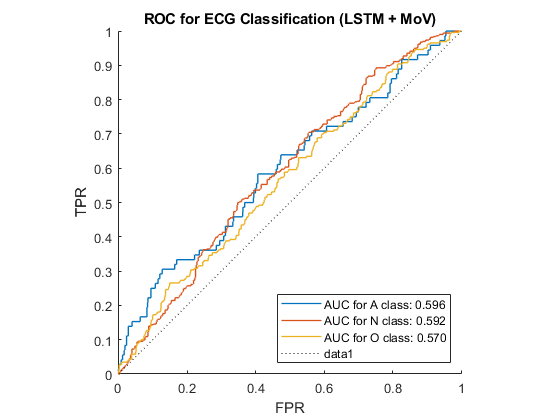



% save('TrainedSVM_mov','net','YTest','TestFeatures','YTrain','TrainFeatures');

classNames = {'A','N','O'};
clf;
hold on
for i=1:3
    [xr, yr, ~, auc] = perfcurve(YTest,scores(:, i), classNames{i});
    plot(xr, yr, 'linewidth', 1)
    legends{i} = sprintf('AUC for %s class: %.3f', classNames{i}, auc);
end

legend(legends, 'location', 'southeast')
line([0 1], [0 1], 'linestyle', ':', 'color', 'k');
xlabel('FPR'), ylabel('TPR')
title('ROC for ECG Classification (LSTM + MoV)')
axis square
hold off

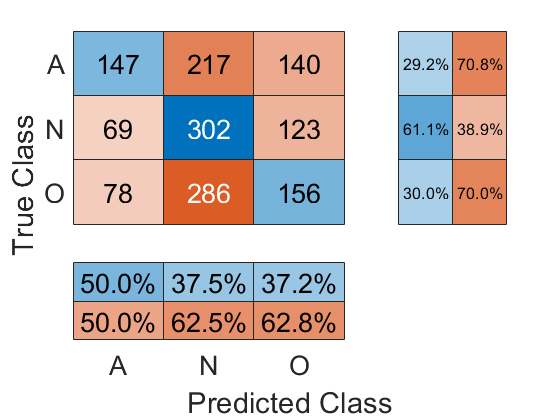

figure
confusionchart(YTest,preds,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','FontSize',20);

save('TrainedLSTM_Wavelet','LSTM','YTest','XTestSD','YTrain','XTrainSD')